% System: Trajectory tracking
clear;
% Ac = [-0.313 56.7 0;-0.0139 -0.426 0;0 56.7 0];
% Bc = [0.232;0.0203;0];
% Cc = [0 0 1];
% Dc = zeros(size(Cc,1),size(Bc,2));
% System: motor position control
J = 3.2284E-6;
b = 3.5077E-6;
KK = 0.0274;
RR = 4;
LL = 2.75E-6;

Ac = [0 1 0; 0 -b/J KK/J; 0 -KK/LL -RR/LL]

Ac = 	1.0e+06 *

         0    0.0000         0
         0   -0.0000    0.0085
         0   -0.0100   -1.4545


Bc = [0; 0; 1/LL]

Bc = 	1.0e+05 *

         0
         0
    3.6364


Cc = [1 0 0]

Cc =      1     0     0


Dc = [0]

Dc = 0


Ts = 0.1; %Probably in seconds

sys_c = ss(Ac,Bc,Cc,Dc);
sys = c2d(sys_c,Ts);

[A,B,C,D] = dssdata(sys)

A =     1.0000    0.0168    0.0001
         0    0.0027    0.0000
         0   -0.0000   -0.0000


B =     2.9794
   35.7308
    0.0052


C =      1     0     0


D = 0


safex = [0.3;0.3;1.5];
depth = 0.1;

size_x = [size(A,2) 1];
size_y = [size(C,1) 1]; 


%p = 500; 
%Q = p*C'*C;
%Q = zeros(size(A));
%R = zeros(size(C,1),size(C,1)); 
% Q = [ 0.5 0 0 ;
%       0 0.1 0;
%       0 0 0.12;
%     ];

% Q = [ 0.3 0 0 ;
%       0 0.5 0;
%       0 0 0.12;
%     ];
% 
% R = 0.001;


Q = [ 1000 0 0 ;
      0 0.1 0;
      0 0 1;
    ];

R = 0.1;
R = R*Ts*Ts;
Q = Q*Ts*Ts;
N = zeros(size(Ac,2),size(Bc,2));
[K] = dlqr(A,B,Q,R,N)

K =     0.3298    0.0056    0.0000


[Kc] = lqr(sys_c,Q,R)

Kc =   100.0000    1.0307    1.1037


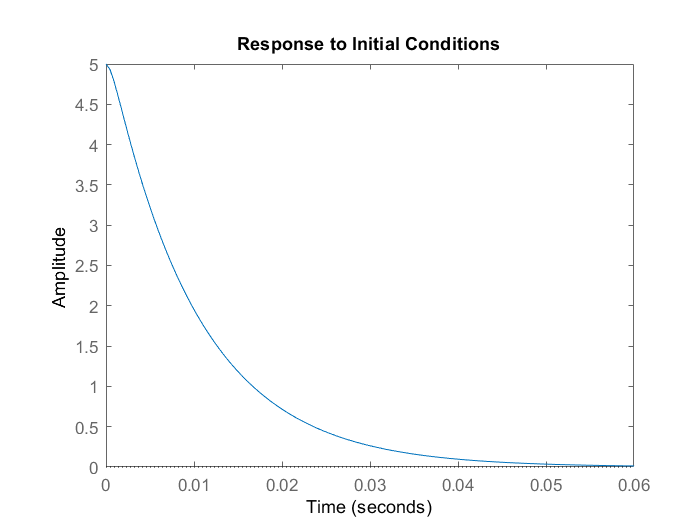

sys_gain_c = ss(Ac-Bc*Kc,Bc,Cc,Dc);

sys_lqr_disc = c2d(sys_gain_c,Ts);

QN = 1;
RN = 10;
sys_gain = ss(A- B*K,B,C,D,Ts);
[kalmf,L,P] = kalman(sys,QN,RN);
[kalmf_gain,L_gain,P_gain] = kalman(sys_gain,QN,RN);


x0 = depth*safex;
x0 = [5; 0; -1000];
initial(sys_gain_c,x0);

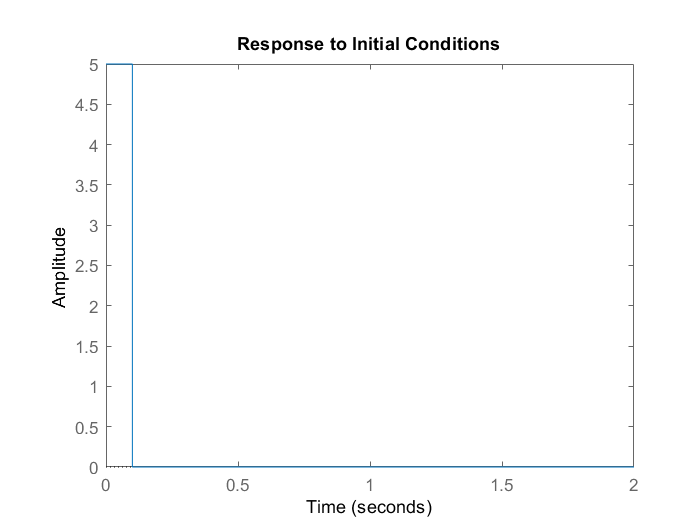


initial(sys_lqr_disc,x0);

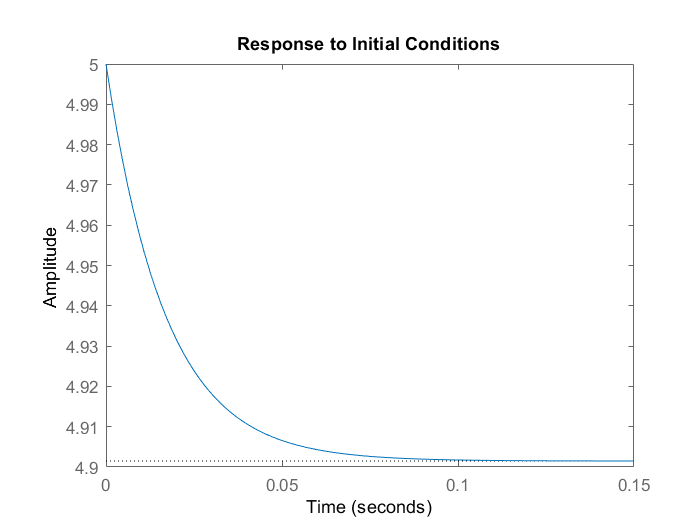


initial(sys_c,x0);

%This plots the output, which is the y = Cx + Du value.
%In this case it is the x[0] value which is the angular position of the
%system
